format long
syms X Y Z psi theta phi;%设置函数自变量
v=[X;Y;Z;psi;theta;phi];
Jg=jacobian(g(v),v);%计算雅克比矩阵
v0=[0;0;20;0;0;0];%设置初始值
J=vpa(subs(Jg,v,v0));%用v0赋值
v1=v0-inv(J)*g(v0);
i=0;%检查迭代次数
while norm(v1-v0)>=10^(-50)%高斯-牛顿迭代法
    v0=v1;
    J=vpa(subs(Jg,v,v0));
    v1=v0-J\g(v0);
    i=i+1;
end
v1%输出结果

$$v1 = \left(\begin{array}{c} -3.4469557159719698762709184208075\\ 7.9676162352545262031121986593474\\ 18.017646567180649830703796022654\\ 0.023390306070863205978518608458176\\ -0.078688271816232459220038102347591\\ 0.19162395249659578930449389902732 \end{array}\right)$$

i%输出迭代次数

i =     23


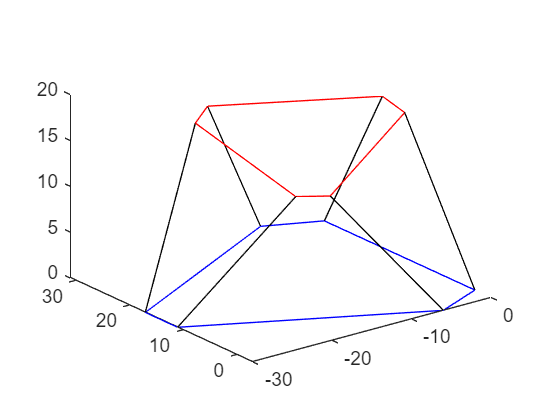

p1=20; p2=25; p3=26; p4=20; p5=20; p6=20;%输入支杆长度
x1=0; x2=-16; x3=-19; x4=-19; x5=-16;%输入平台顶点横坐标
y1=4; y2=13; y3=11; y4=-7; y5=-9;%输入平台顶点纵坐标
xx1=0;xx2=-6; xx3=-30; xx4=-30; xx5=-6;%输入平台底座定点横坐标
yy1=28; yy2=31; yy3=17; yy4=11; yy5=-3;%输入平台底座定点纵坐标
X1=v1(1);
Y1=v1(2);
Z1=v1(3);
psi1=v1(4);
theta1=v1(5);
phi1=v1(6);
p=[p1;p2;p3;p4;p5;p6];
T=[X1;Y1;Z1];%平移矩阵
R=[cos(psi1) -sin(psi1) 0;sin(psi1) cos(psi1) 0;0 0 1]*[cos(theta1) 0 sin(theta1);0 1 0;-sin(theta1) 0 cos(theta1)]*[1 0 0;0 cos(phi1) -sin(phi1);0 sin(phi1) cos(phi1)];
%旋转矩阵
xp=[0,x1,x2,x3,x4,x5];
yp=[0,y1,y2,y3,y4,y5];
z=zeros(1,6);
A=[xp;yp;z];
xb=[0,xx1,xx2,xx3,xx4,xx5];
yb=[0,yy1,yy2,yy3,yy4,yy5];
B=[xb;yb;z];
for i=1:6
    A(:,i)=T+R*A(:,i);%计算平台各顶点新的坐标
end
plot3([A(1,:),A(1,1)],[A(2,:),A(2,1)],[A(3,:),A(3,1)],'r');hold on
plot3([B(1,:),B(1,1)],[B(2,:),B(2,1)],[B(3,:),B(3,1)],'b');hold on
for i=1:6
    plot3([A(1,i),B(1,i),A(1,i)],[A(2,i),B(2,i),A(2,i)],[A(3,i),B(3,i),A(3,i)],'k');hold on
end%画出三维图


g(v1)

$$ans = \left(\begin{array}{c} 0\\ 0\\ 0\\ 0\\ 0\\ 0 \end{array}\right)$$

function out=g(v)
p1=20; p2=25; p3=26; p4=20; p5=20; p6=20;%输入支杆长度
x1=0; x2=-16; x3=-19; x4=-19; x5=-16;%输入平台顶点横坐标
y1=4; y2=13; y3=11; y4=-7; y5=-9;%输入平台顶点纵坐标
xx1=0;xx2=-6; xx3=-30; xx4=-30; xx5=-6;%输入平台底座定点横坐标
yy1=28; yy2=31; yy3=17; yy4=11; yy5=-3;%输入平台底座定点纵坐标
X=v(1);
Y=v(2);
Z=v(3);
psi=v(4);
theta=v(5);
phi=v(6);
p=[p1;p2;p3;p4;p5;p6];
T=[X;Y;Z];%平移矩阵
R=[cos(psi) -sin(psi) 0;sin(psi) cos(psi) 0;0 0 1]*[cos(theta) 0 sin(theta);0 1 0;-sin(theta) 0 cos(theta)]*[1 0 0;0 cos(phi) -sin(phi);0 sin(phi) cos(phi)];
%旋转矩阵
xp=[0,x1,x2,x3,x4,x5];
yp=[0,y1,y2,y3,y4,y5];
z=zeros(1,6);
A=[xp;yp;z];
xb=[0,xx1,xx2,xx3,xx4,xx5];
yb=[0,yy1,yy2,yy3,yy4,yy5];
B=[xb;yb;z];
for i=1:6
    l(:,i)=T+R*A(:,i)-B(:,i); 
end
for i=1:6
    out(i,1)=(p(i,1))^2-(l(:,i))'*l(:,i);%导出gi,合并为g
end
end